Reading "../waves/recordings/wavetable/SINE.wav" ...


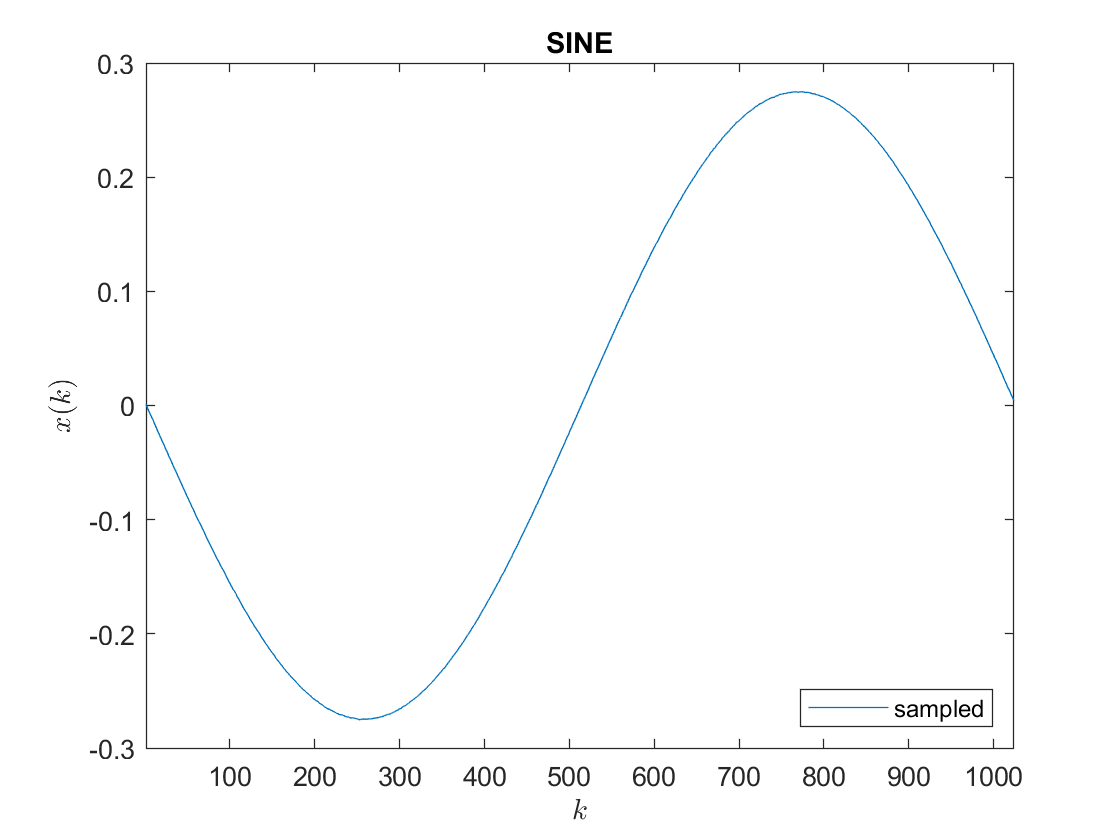

Writing "../waves/wavetable/sampled/SINE.wav" ...


Reading "../waves/recordings/wavetable/SAW1.wav" ...


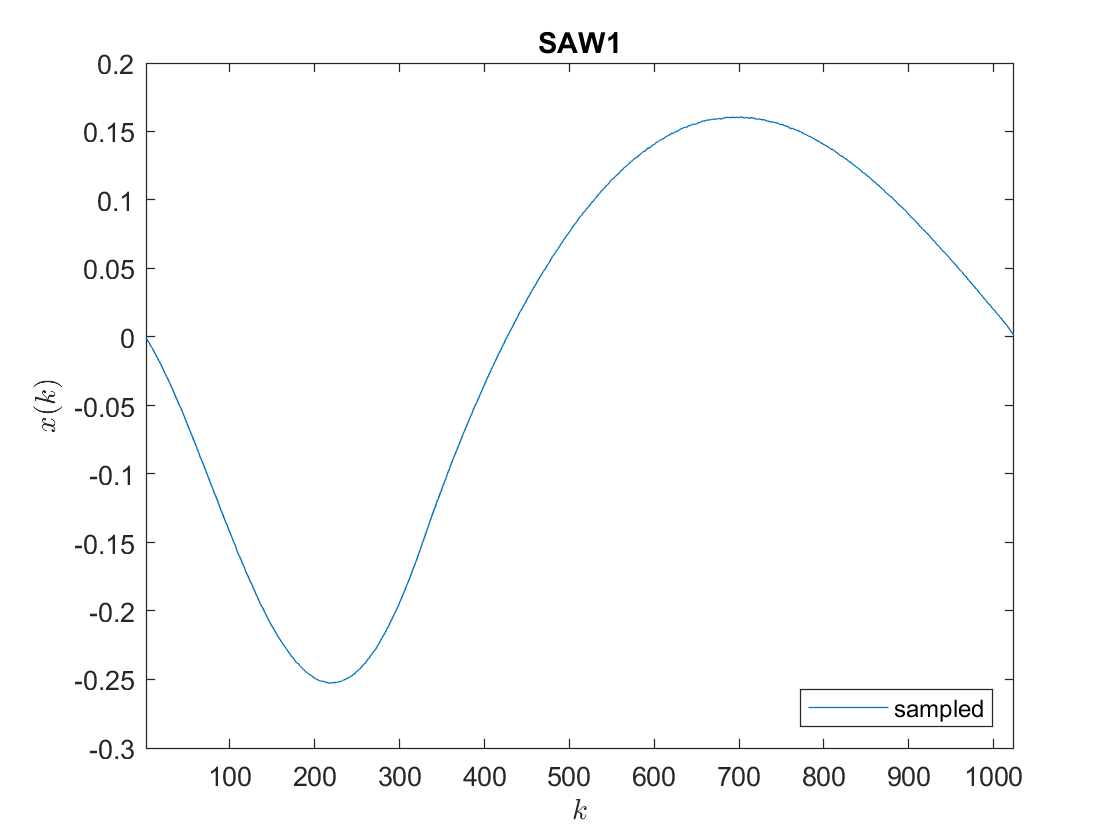

Writing "../waves/wavetable/sampled/SAW1.wav" ...


Reading "../waves/recordings/wavetable/SAW2.wav" ...


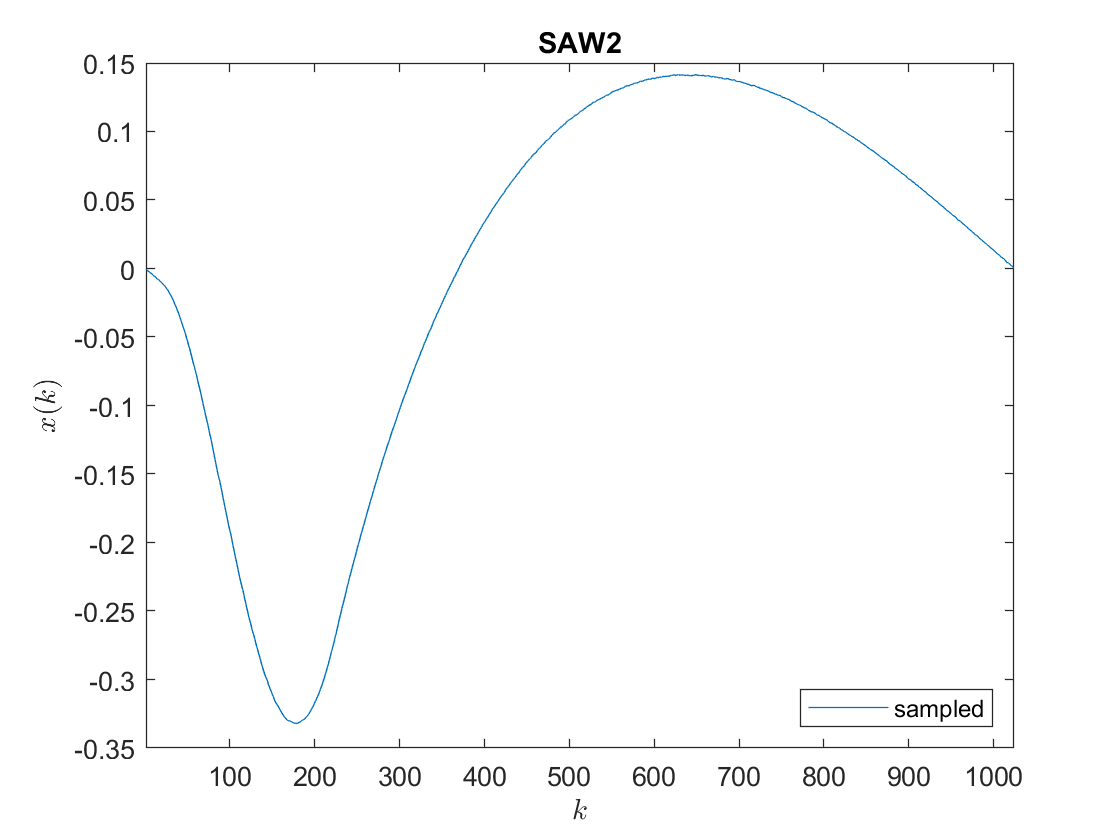

Writing "../waves/wavetable/sampled/SAW2.wav" ...


Reading "../waves/recordings/wavetable/SAW3.wav" ...


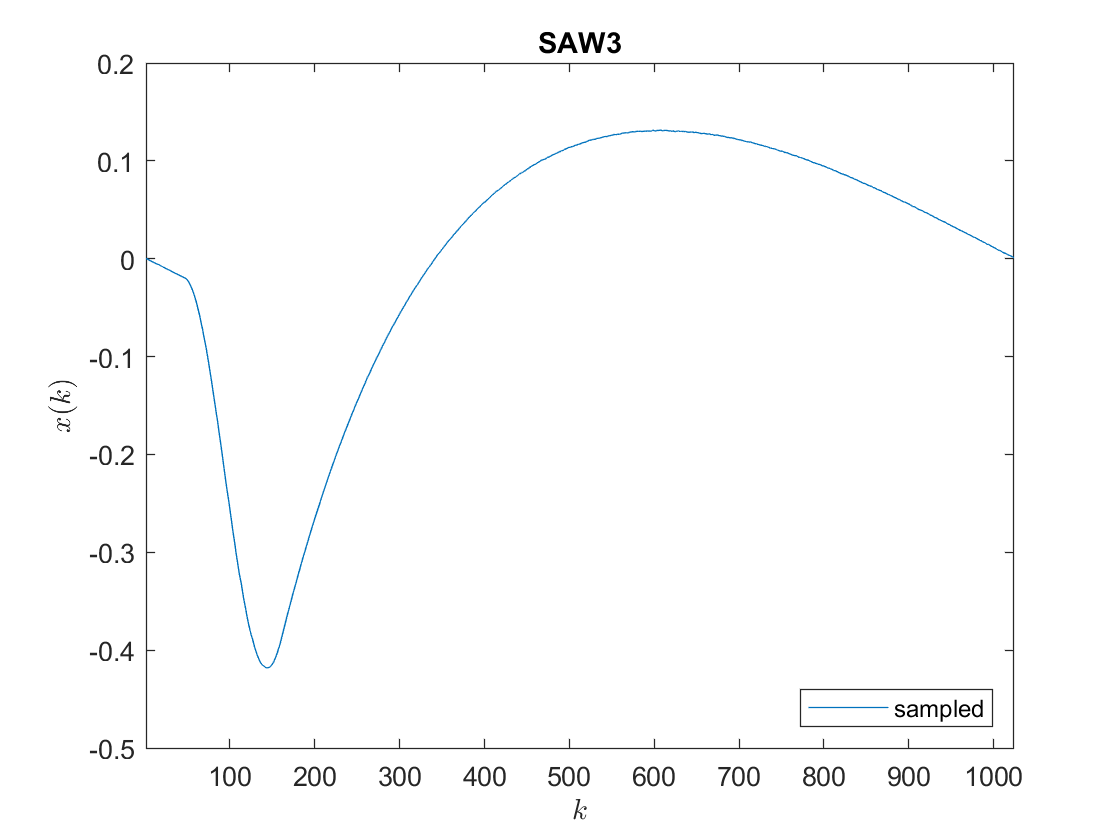

Writing "../waves/wavetable/sampled/SAW3.wav" ...


Reading "../waves/recordings/wavetable/SAW4.wav" ...


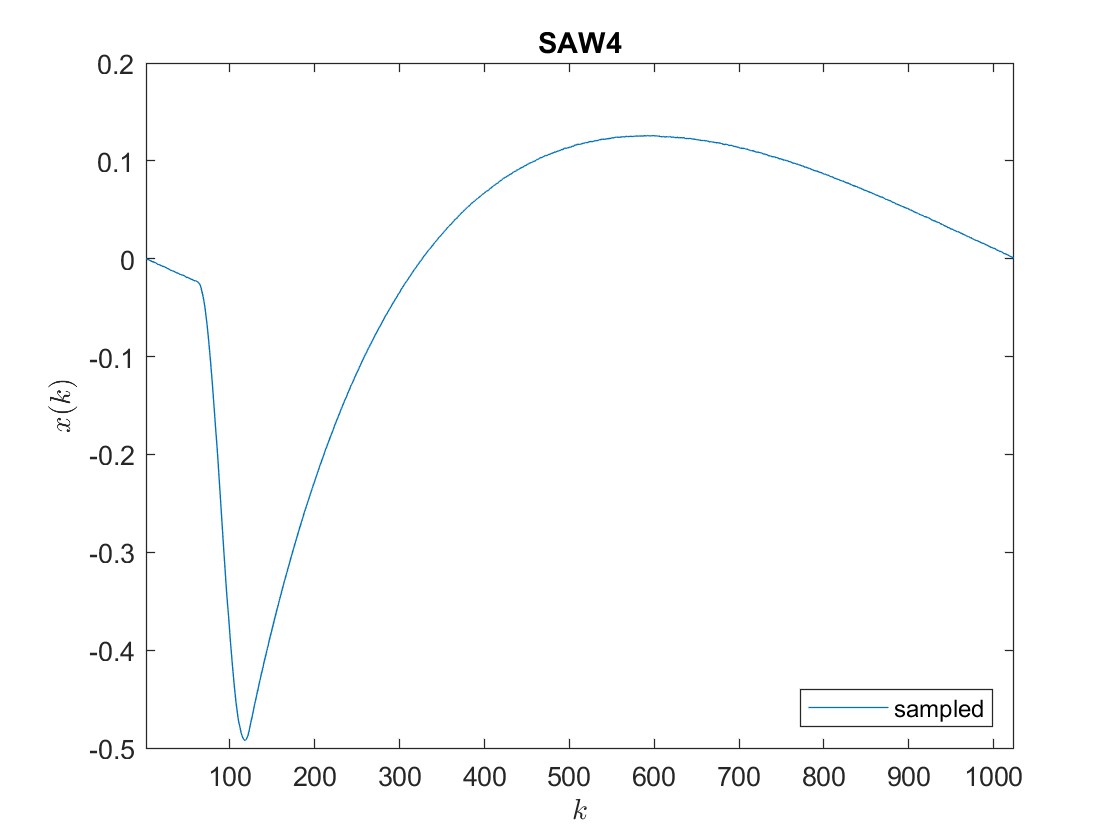

Writing "../waves/wavetable/sampled/SAW4.wav" ...


Reading "../waves/recordings/wavetable/SAW5.wav" ...


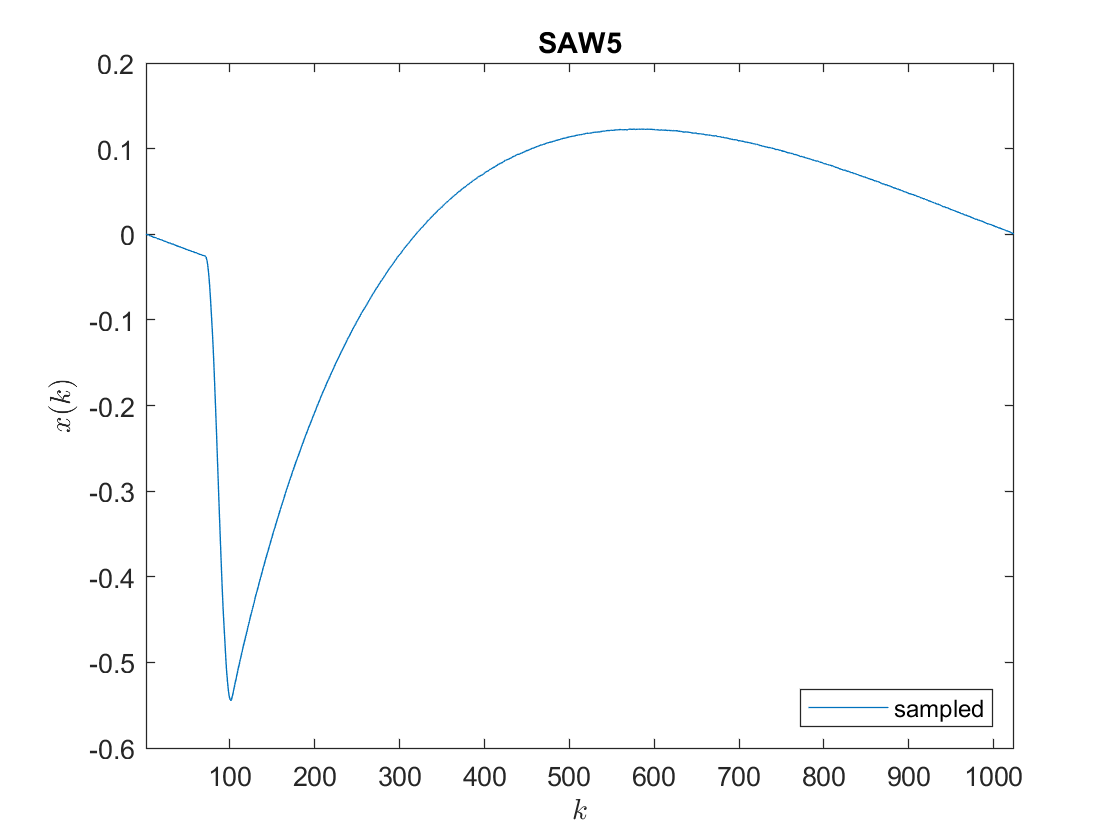

Writing "../waves/wavetable/sampled/SAW5.wav" ...


Reading "../waves/recordings/wavetable/NOISE1.wav" ...


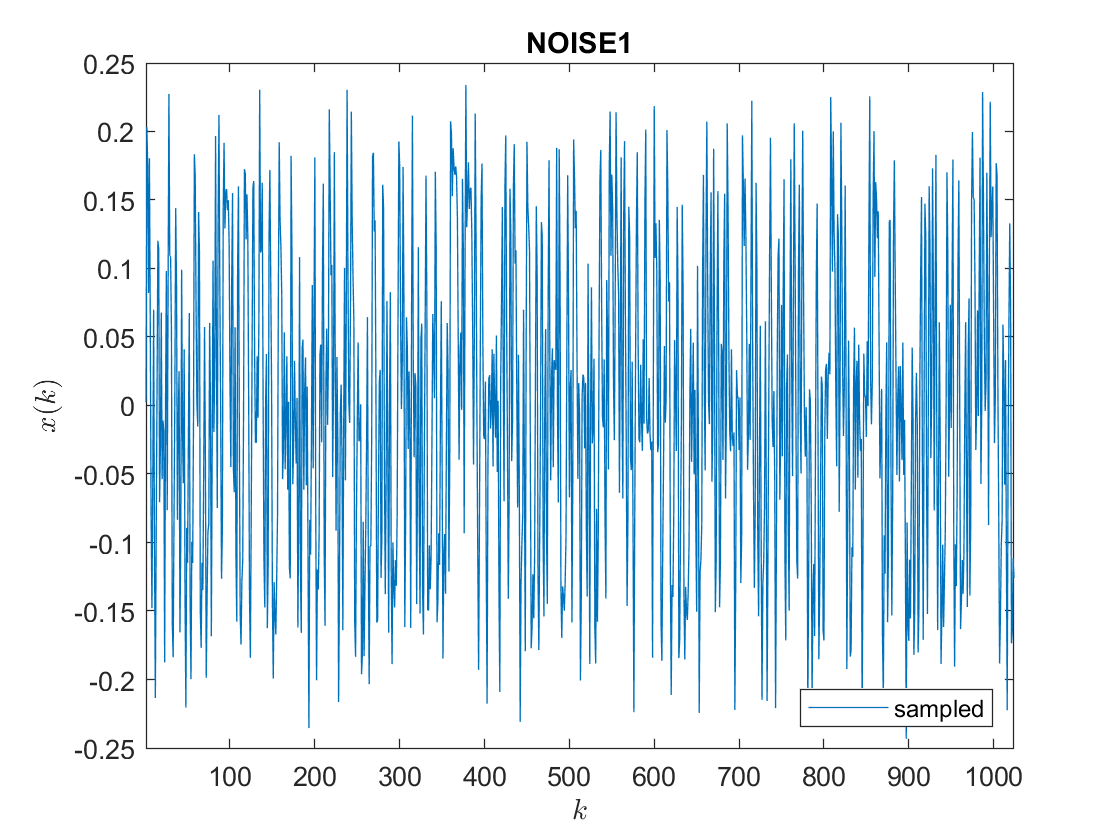

Writing "../waves/wavetable/sampled/NOISE1.wav" ...


Reading "../waves/recordings/wavetable/NOISE2.wav" ...


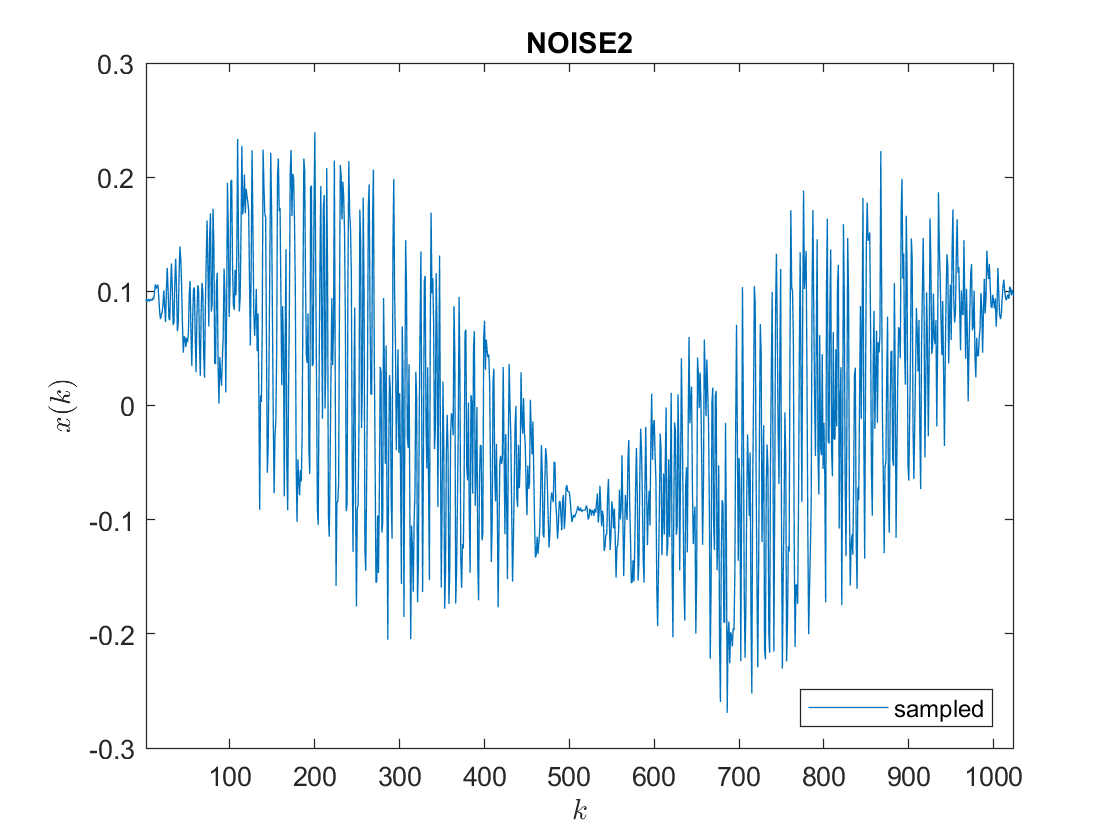

Writing "../waves/wavetable/sampled/NOISE2.wav" ...


% See <vVZ>/waves/recordings/README.md for description!

f_S  = 48000;
name = ["SINE";"SAW1";"SAW2";"SAW3";"SAW4";"SAW5";"NOISE1";"NOISE2"];
k_S  = [ 11833; 14036; 12222; 12336; 18400; 13068;   33521;   31777];
K    = 1024;
wave = cell(length(name));

for i=1:length(name)
  fnIn  = '../waves/recordings/wavetable/'+name(i)+'.wav';
  fnOut = '../waves/wavetable/sampled/'   +name(i)+'.wav';
  fprintf('Reading \"%s\" ...\n',fnIn);
  wave{i} = audioread(fnIn,[k_S(i)+1,k_S(i)+K]);
  wave{i} = wave{i}-mean(wave{i});      % Remove DC
  %wave{i} = wave{i}./max(abs(wave{i})); % Normalize
  figure; plot(wave{i});
  title(name(i));
  legend({'sampled'},'Location','southeast');
  xlabel('$$k$$'   ,'Interpreter','latex'); xlim([1 K]);
  ylabel('$$x(k)$$','Interpreter','latex');
  fprintf('Writing \"%s\" ...\n',fnOut);
  audiowrite(fnOut,wave{i},f_S);
end